# **Effective Solar House Design**

*Authors: *Drew Pang and Kelly Stellmacher

## Question:

Traditional houses attempt to separate the temperature-controlled air from the outside air but add windows to let in natural light. While these homes have gotten more energy efficient due to advances in insulation, solar houses can be more energy efficient. By contrast, solar homes attempt to heat themselves through large windows facing south. During Winter, the sun shines into the house and radiates heat energy off of the floor. However, during the Summer when the sun is higher, the soffit blocks the sun from entering the already warm house. 

 We can use thermodynamics to model a solar house to estimate the effects of parameters. Let's take a look at the specific solar house we are modeling:

**Question:** What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?

Why is this interesting? We are asking a design question, and through our model, we will be able to determine the effects of the thickness of our walls. This may help architects and homeowners looking to design and build solar houses.

## **Method/model:**

We are going to answer our question by tracking the flow of energy from the sun into the floor, then into the room and out the walls. This will allow us to determine the change in temperature of the room over time. We began with energy transferring directly from the sun into the room but added an intermediary stock that stores the energy from the sun before emitting it into the room. We also grappled with the possibility of adding another convective flow from the walls of the house to the outside air but decided to begin with a conduction flow through the walls.

We developed the following schematic diagram:

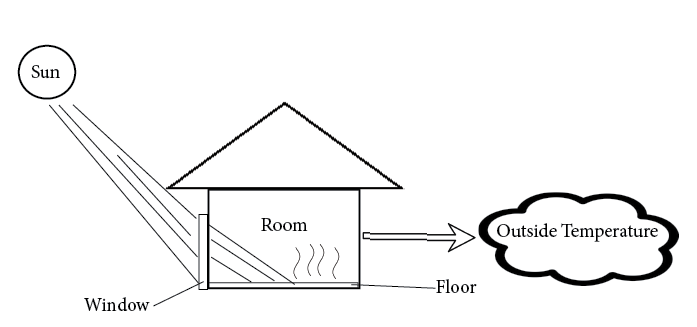

Where energy radiates from the sun, through the window of the house, into the floor, and then conducts from the floor into the air contained in the house. The energy then leaves the house via convecting through the walls. 

From the schematic, we developed the following stock and flow diagram:

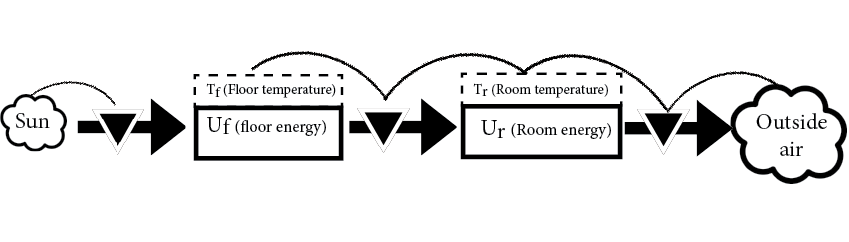

Where energy flows from the Sun to Uf (the stock of energy in the floor), then to Ur (the stock of energy in the room), then out of the room into the outside air. The flow from the sun to the floor is radiation, the flow from the floor to the room is convection, and the flow from the room to the outside air is conduction.

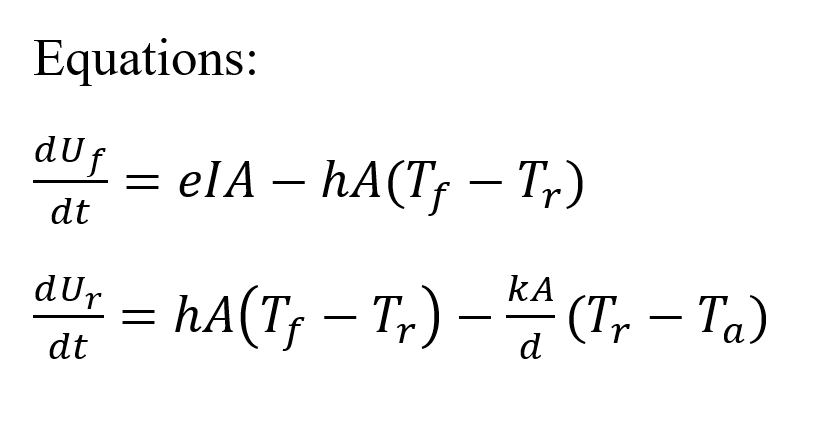

Through research into the different parameters of the system, we managed to gain reliable approximations for all of the factors contributing to our model. The parameter values needed to be revised multiple times to create a more accurate model.

**Parameters**: 

- Tf_0 = 293 K, floor starting temperature

- Tr_0 = 293 K, house int starting temperature

- Ta = 263.56 K, environment temperature$^1$

- w = 10m, sidelength of house

- wt = 0.1-0.5m, thickness of walls  

- wf = 0.05715m, thickness of floor$^2
$

- I = 170.14 W/m^2 incident solar radiation$^3

$ 

- e = 0.473 J/m^2, emmisivity of oak floor$^4$ 

- h_a = 0.026 W/m, thermal conductivity of air$^5$

- h_w = 0.05 W/m, thermal conductivity of insulation walls$^6$ 

- h_f = 0.170 W/m, thermal conductivity of wood floor$^7
$

- s_f = 1850 J/kg C, specific heat of wood floor$^8$

- s_a = 1005 J/kg C, specific heat of air$^9$

- d = 1.293 kg/m^3, density of air$^{10}$ 

- d_f = 745 kg/m^3, density of wood floor$^{11}$ 

$^1$ (*Columbus December Weather, Average Temperature (Ohio, United States) - Weather Spark*, n.d.)

$^2
$(*What Is the Best Thickness for Wood Flooring?*, n.d.)

$^3

$(*Data.GISS: Insolation at Specified Location*, n.d.)

$^4$(*Polytec - Decorative Surfaces and Doors for Kitchens, Laundries, Wardrobes, Furniture, and Commercial Use.*, n.d.)

$^5$(*Thermal Conductivity of Common Materials | Neutrium*, n.d.)

$^6$(“Thermal Conductivity of Insulation - Steady State & Transient Method,” 2019)

$^7
$(*Thermal Conductivity of Common Materials | Neutrium*, n.d.)

$^8$(Radmanović et al., 2014)

$^9
$(*Specific Heat Capacities of Air - (Updated 7/26/08)*, n.d.)

$^{10}$(*Air Density | Glossary*, n.d.)

$^{11}$(*Density of Wood in Kg/M3, g/Cm3, Lb/Ft3 – the Ultimate Guide - Matmatch*, n.d.)

Assumptions for our model include:

- The structural integrity of the house will not be jeopardized due to walls made purely of insulation.

- The roof is made of the same material as the walls. 

- The aperture of the window will remain constant.

- The Sun's rays remain at the same angle throughout the day; this angle is the average Sun zenith angle during the Winter.

- The house is empty; no people or furniture are present to alter the energy content of the room.

- Nothing is obstructing the sunlight from reaching the house. 

- The heat conducted through the window is the same per unit of area as the walls. 

- The aperture of the Sun is situated such that the entire floor is illuminated by sunlight.

All of these assumptions are made to keep the model simple and possible to program. However, if we wished to increase the accuracy, we could take our assumptions and act on them. For example, if we wanted to make the house realistically liveable, we would have to account for structural integrity and openings where people can enter and exit. 

With these stocks, flows, parameters, and assumptions, we can implement our model in code with a default wall thickness of 0.3m as such:

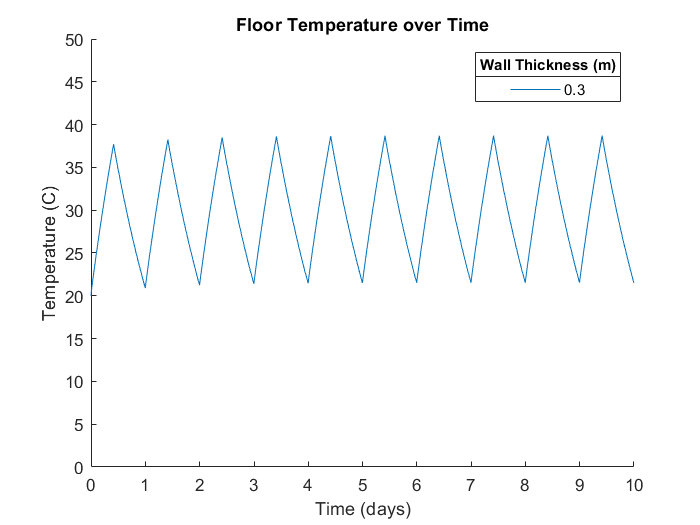

% Create figure
figure(1);
clf; hold on;
wt = 0.3; % Set wall thickness to 0.3m
[Tt,Dt] = solar_house_day_night(wt); % Run simulation
plot(Tt/(24*3600),Dt(:,1)); % Plot simulation

% Set graph parameters
title('Floor Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
ylim([0 50])
legend('0.3')
title(legend,'Wall Thickness (m)')

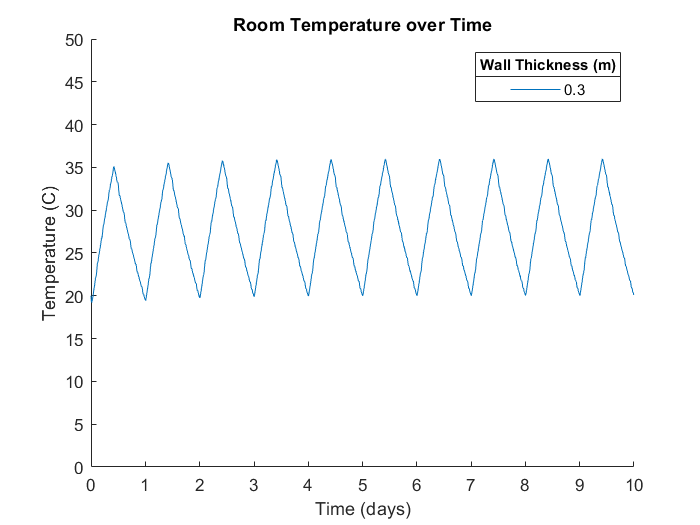

% Create figure
figure(2)
clf; hold on;
wt = 0.3; % Set wall thickness to 0.3m
[Tt,Dt] = solar_house_day_night(wt); % Run simulation
plot(Tt/(24*3600),Dt (:,2)); % Plot simulation

% Set graph parameters
title('Room Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
ylim([0 50])
 legend('0.3')
title(legend,'Wall Thickness (m)')

**Model Verification:**

Verifying this model is difficult because the total energy cannot be tracked, as it is contained in stocks that are not fully monitored. For example, the energy leaving the room into the outside air is contained in the walls before it is released, leading to an unknown stock. 

By printing a few of the energy in and out values from within the rate function for ode45 for the floor and room, we can see that they are fairly reasonable. Instead of millions of joules or millijoules, we are consistently getting thousands of joules, which make sense for our house size.

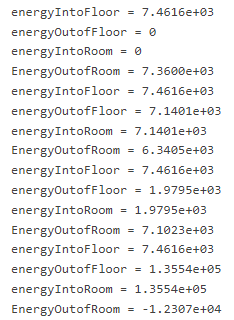

**Model validation:**

If we had more time and resources for this project, we could validate the results by constructing a miniature model house with the materials we specified, setting up a controllable heat source, then monitoring the change in temperature over time.

## **Results:**

Now that we have a model, we can sweep the wall thickness parameter to see how it affects the temperature over time. We will sweep the wall thickness between 0.1-0.5m in 0.1m increments.

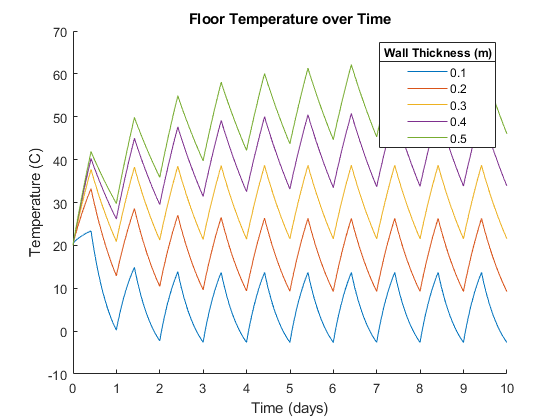

% Create figure and set graph parameters
figure(1);
clf; hold on;
title('Floor Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')

% Parameter sweep and set wall thickness for each variation
for wt = 0.1:0.1:0.5;
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt(:,1));
end

% Set additional graph parameters
 legend('0.1', '0.2', '0.3', '0.4','0.5')
 title(legend,'Wall Thickness (m)')

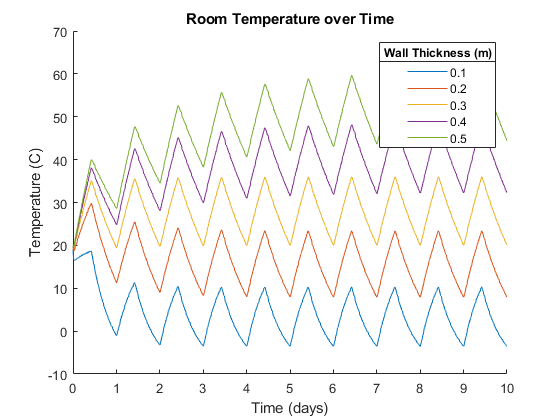

% Creat figure and set graph parameters
figure(2)
clf; hold on;
title('Room Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
 
% Parameter sweep and set wall thickness for each variation
for wt = 0.1:0.1:0.5
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt (:,2));
end 

% Set additional graph parameters
legend('0.1', '0.2', '0.3', '0.4','0.5')
title(legend,'Wall Thickness (m)')

Sweeping the parameter of the wall thickness yields an incremental increase in room temperature as the wall's thickness increases. The majority of wall thicknesses render the room temperature too hot for humans to survive living in it. 

The highest thickness of 0.5m causes the room to heat to a maximum temperature of over 60 degrees Celcius during the day and about 45 degrees Celcius during the night. On the other hand, the lowest thickness of 0.1m results in a drop to below zero during the night, which is livable, but not ideal living conditions. The only thickness that preserves a range of livable temperatures over time is 0.2m because it causes the temperature to rise to about 28 and fall to about 10 degrees Celsius. 

## **Interpretation:**

**Answering the question:**

Our question was 'What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?' The quick answer is that any thickness greater than 0.2 will yield a minimum internal temperature. However, the ideal thickness is about 0.2m because this also prevents the maximum temperature from exceeding a tolerable level. 

**Values:**

This answer is good in that it reveals more about the situation than was initially expected. We were concerned about the house becoming too cold, but the model signified that the true situation may cause the house to become too hot. Despite its values, it is important to keep in mind that this model is limited in multiple manners. 

**Limitations:**

Our model is limited in that it only accounts for conduction through the walls and fails to account for doors or open windows where energy could convect directly out of the house, which could cause the temperature inside to decrease at a faster rate. It is also limited to a very specific location with a specific amount of solar radiation acting on it. Our model also sets the insolation to the mean during the day and zero during the night instead of following a normal distribution.

**Iterations:**

If we were to continue iterating on our model, we could lengthen the timeframe to a year and examine the impact of changing seasons. We could also add a flow from the floor into the ground to more accurately simulate the change in energy in the house.

## Citations:

*5 Proven Hardwood Flooring Thickness Categories*. (n.d.). Easiklip Floors. Retrieved November 3, 2021, from [https://easiklip.com/blogs/diy-hardwood-floor-blog/5-proven-hardwood-floor-thickness-categories](https://easiklip.com/blogs/diy-hardwood-floor-blog/5-proven-hardwood-floor-thickness-categories) 

*Air Density | Glossary*. (n.d.). MinebeaMitsumi Product DataBase. Retrieved November 3, 2021, from [https://product.minebeamitsumi.com/en/faq/glossary/detail/post_34.html](https://product.minebeamitsumi.com/en/faq/glossary/detail/post_34.html) 

*Columbus December Weather, Average Temperature (Ohio, United States)—Weather Spark*. (n.d.). Retrieved November 3, 2021, from [https://weatherspark.com/m/17263/12/Average-Weather-in-December-in-Columbus-Ohio-United-States](https://weatherspark.com/m/17263/12/Average-Weather-in-December-in-Columbus-Ohio-United-States) 

*Data.GISS**: Insolation at Specified Location*. (n.d.). Retrieved November 3, 2021, from [https://data.giss.nasa.gov/modelE/ar5plots/srlocat.html](https://data.giss.nasa.gov/modelE/ar5plots/srlocat.html) 

*Density of wood in kg/m3, g/cm3, **lb**/ft3 – the ultimate guide—**Matmatch*. (n.d.). Retrieved November 3, 2021, from [https://matmatch.com/learn/property/density-of-wood](https://matmatch.com/learn/property/density-of-wood) 

*polytec**—Decorative surfaces and doors for kitchens, laundries, wardrobes, furniture, and commercial use.* (n.d.-a). Retrieved November 3, 2021, from [https://www.polytec.com.au/](https://www.polytec.com.au/) 

*polytec**—Decorative surfaces and doors for kitchens, laundries, wardrobes, furniture, and commercial use.* (n.d.-b). Retrieved November 3, 2021, from [https://www.polytec.com.au/](https://www.polytec.com.au/) 

*Polytec-technical-light-reflectance-value.pdf*. (n.d.). Retrieved November 3, 2021, from [https://www.polytec.com.au/docs/technical/polytec-technical-light-reflectance-value.pdf](https://www.polytec.com.au/docs/technical/polytec-technical-light-reflectance-value.pdf) 

Radmanović, K., Đukić, I., & Pervan, S. (2014). Specific Heat Capacity of Wood. *Drvna** Industrija*, *65*, 151–157. [https://doi.org/10.5552/drind.2014.1333](https://doi.org/10.5552/drind.2014.1333) 

*Specific Heat Capacities of Air**—(**Updated 7/26/08)*. (n.d.). Retrieved November 3, 2021, from [https://www.ohio.edu/mechanical/thermo/property_tables/air/air_Cp_Cv.html#:~:text=The%20nominal%20values%20used%20for,v%20%3D%200.718%20kJ%2Fkg](https://www.ohio.edu/mechanical/thermo/property_tables/air/air_Cp_Cv.html#:~:text=The%20nominal%20values%20used%20for,v%20%3D%200.718%20kJ%2Fkg) 

*Sunrise and sunset times in Columbus, December 2021*. (n.d.). Retrieved November 3, 2021, from [https://www.timeanddate.com/sun/usa/columbus?month=12](https://www.timeanddate.com/sun/usa/columbus?month=12) 

*Thermal Conductivity of Common Materials | **Neutrium*. (n.d.). Retrieved November 3, 2021, from [https://neutrium.net/heat-transfer/thermal-conductivity-of-common-materials/](https://neutrium.net/heat-transfer/thermal-conductivity-of-common-materials/) 

Thermal Conductivity of Insulation—Steady State & Transient Method. (2019, December 6). *C-**Therm** Technologies Ltd.* [https://ctherm.com/resources/newsroom/blog/thermal-conductivity-testing-insulation-traditional-steady-state-accelerated-transient-methods/](https://ctherm.com/resources/newsroom/blog/thermal-conductivity-testing-insulation-traditional-steady-state-accelerated-transient-methods/) 

*What is the best thickness for wood flooring?* (n.d.). Retrieved November 3, 2021, from [https://truediy.net/learn/what-is-the-best-thickness-for-wood-flooring/](https://truediy.net/learn/what-is-the-best-thickness-for-wood-flooring/) 